% 清空工作空间，关闭所有图形，清除命令窗口
clear;
close all;
clc;

## 参数定义

% 目标通道数和参考通道数
chan_num_tar = 2;
chan_num_ref = 1;
chan_num_total = chan_num_tar + chan_num_ref;

% 数据总时长
total_duration = 9;

% 载波频率
f_c = 0.5e9;

% 采样频率
f_s = 1e6;

% 与模糊函数相关的参数
CIT = 0.1; 
CIT_region = CIT * f_s;

% 滑动窗口的数量
N_slide = 10;

% 将 0.1s 的数据切割成 N_slide 份，滑动的步长
T_slide = CIT / N_slide;

% 最大多普勒频率和步长
max_dop = 1000;
step_dop = 1 / CIT;
array_Doppler_frequency = -max_dop:step_dop:max_dop;

% 数据文件的路径
filename_data = 'D:\Github\Passive-Handwriting-Tracking\data\w10_1.bin';

% 以二进制形式打开文件
fid1 = fopen(filename_data, 'rb');  
% 将文件指针移动到文件末尾
fseek(fid1, 0, 'eof');  
% 获取文件长度
fsize = ftell(fid1);  

% 总采样点数，每个采样点由实部和虚部组成
total_samplelen = fsize / 4;  

% 单通道的采样点数
sample_1channel = 1996; 

% 一个 block 的长度 = 通道数 * 单位长度
samplelen = sample_1channel * chan_num_total; 
% 循环次数 = 向下取整(总长度/一个 block 长度)
loopNum = floor(total_samplelen / samplelen); 
% 一个通道的采样点数，用于创建一个矩阵来存放数据
samples_per_chan = sample_1channel * loopNum;

% 关闭文件
fclose(fid1);

## Read Calibration File

% 以二进制形式打开文件
fid_cali = fopen(filename_data, 'rb');
% 将文件指针移动到文件开头
fseek(fid_cali, 0, 'bof');
% 创建一个大小为 chan_num_total x samples_per_chan 的矩阵，用于存储数据
chan_seq_cali = zeros(chan_num_total, samples_per_chan);

% 循环读取数据块并填充矩阵
for loopIdx = 1:loopNum
    % 从文件中读取一块数据，每个数据点包含实部和虚部，数据类型为 int16，字节序为 little-endian
    [data, ~] = fread(fid_cali, [2, sample_1channel * chan_num_total], 'int16', 'l');
    
    % 遍历通道数
    for idx_chan = 0:chan_num_total-1
        % 计算每个通道的数据在矩阵中的位置
        frame_start = sample_1channel * (0 + idx_chan) + 1;
        frame_end = sample_1channel * (1 + idx_chan);
        
        % 将实部和虚部组合成复数并填充矩阵
        chan_seq_cali(idx_chan + 1, (loopIdx - 1) * sample_1channel + 1 : loopIdx * sample_1channel) = ...
            data(1, frame_start:frame_end) + 1i * data(2, frame_start:frame_end);
    end
end

% 关闭文件
fclose(fid_cali);

## 绘图检查接收信号是否正确

offset = 1000;
ChannelIdx = 1;
EndSearch = samples_per_chan;
StartSearch = 1+offset;

% figure(1)
% for idxChannel = 1:chan_num_total
%     subplot(chan_num_total,1,idxChannel)
%     plot(real(chan_seq_cali(idxChannel,StartSearch:EndSearch)));
%     hold on;
%     plot(imag(chan_seq_cali(idxChannel,StartSearch:EndSearch)));
%     hold off;
% end
% sgtitle('实际接收到的信号');% 整体
% figure(2)
%
% for idxChannel = 1:chan_num_total
%     subplot(chan_num_total,1,idxChannel)
%     pwelch(chan_seq_cali(idxChannel,StartSearch:EndSearch),[],[],[],f_s,'centered','psd');
% end
% sgtitle('psd');%整体

## 数据处理

% 设置数据点的数量
data_count = 2184 * 1;

% 从 chan_seq_cali 中提取参考信号和目标信号
S_ref = chan_seq_cali(3, 1:data_count);
S_tar = chan_seq_cali(1, 1:data_count);

% 计算参考信号和目标信号的互相关
h_temp = xcorr(S_ref, S_tar);

% 获取互相关矩阵的大小
[row_h, col_h] = size(h_temp);
col_h = col_h + 1;

% 设置 N 的值
N = floor(CIT * f_s) / 1000 - 1;

% 寻找互相关的最大值
col_max = find(max(abs(h_temp(col_h/2-N:col_h/2+N))) == abs(h_temp(col_h/2-N:col_h/2+N)));
array_sample_shift = col_max - N - 1;

% 从 chan_seq_cali 中提取目标和两个参考信号
S_tar = chan_seq_cali(1, :);
S_ref1 = chan_seq_cali(2, :);
S_ref2 = chan_seq_cali(3, :);

% 根据计算得到的 array_sample_shift 对数据进行对齐
if array_sample_shift > 0
    data_cor1(1, :) = chan_seq_cali(1, 1 + array_sample_shift:end);
    data_cor1(2, :) = chan_seq_cali(2, 1:end - array_sample_shift);
    data_cor2(1, :) = chan_seq_cali(1, 1 + array_sample_shift:end);
    data_cor2(2, :) = chan_seq_cali(3, 1:end - array_sample_shift);
else
    data_cor1(1, :) = chan_seq_cali(1, 1:end + array_sample_shift);
    data_cor1(2, :) = chan_seq_cali(2, 1 - array_sample_shift:end);
    data_cor2(1, :) = chan_seq_cali(1, 1:end + array_sample_shift);
    data_cor2(2, :) = chan_seq_cali(3, 1 - array_sample_shift:end);
end

% 设置滑动窗口的起始时间
array_start_time = 0:T_slide:total_duration - CIT;

% 初始化用于存储结果的矩阵
A_TD = zeros(length(array_start_time), length(array_Doppler_frequency));
A_TD2 = zeros(length(array_start_time), length(array_Doppler_frequency));

% ref_array 里装着参考对齐后的数据
ref_array = data_cor1(1, :);
% tar_array 里装着监视1对齐后的数据
tar_array = data_cor1(2, :);

% ref_array2 里装着参考对齐后的数据, 和 ref_array 里的数据一模一样
ref_array2 = data_cor2(1, :);
% tar_array2 里装着监视2对齐后的数据
tar_array2 = data_cor2(2, :);

% 数据处理
ref_integer = zeros(length(array_start_time), CIT_region);
tar_integer = zeros(length(array_start_time), CIT_region);
ref_integer2 = zeros(length(array_start_time), CIT_region);
tar_integer2 = zeros(length(array_start_time), CIT_region);

% 分类并填写 FFT 数组表
for i = 1:length(array_start_time) - 2
    ref_integer(i, :) = ref_array((round(array_start_time(i) * f_s + 1)):(round(array_start_time(i) * f_s) + round(CIT * f_s)));
    tar_integer(i, :) = tar_array((round(array_start_time(i) * f_s + 1)):(round(array_start_time(i) * f_s) + round(CIT * f_s)));
end

% 分类并填写 FFT 数组表（第二组数据）
for i = 1:length(array_start_time) - 2
    ref_integer2(i, :) = ref_array2((round(array_start_time(i) * f_s + 1)):(round(array_start_time(i) * f_s) + round(CIT * f_s)));
    tar_integer2(i, :) = tar_array2((round(array_start_time(i) * f_s + 1)):(round(array_start_time(i) * f_s) + round(CIT * f_s)));
end

% FFT 计算
for i = 1:length(array_start_time) - 2
    final = fftshift(fft(tar_integer(i, :) .* conj(ref_integer(i, :)), CIT_region));
    A_TD(i, :) = final(CIT_region/2 + 1 - max_dop/step_dop : CIT_region/2 + 1 + max_dop/step_dop);
    final2 = fftshift(fft(tar_integer2(i, :) .* conj(ref_integer2(i, :)), CIT_region));
    A_TD2(i, :) = final2(CIT_region/2 + 1 - max_dop/step_dop : CIT_region/2 + 1 + max_dop/step_dop);
end

绘图

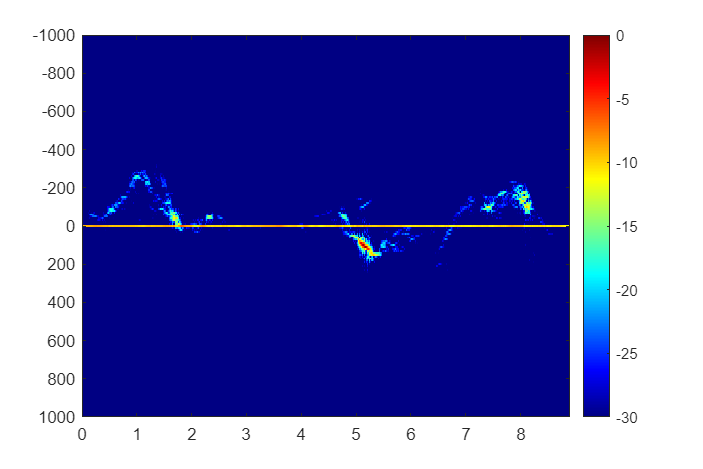

thres_A_TRD = -30;

fig1 = figure(1);
set(fig1, 'position', [50, 50, 900, 600]);
plot_A_DT = abs(A_TD');
plot_A_DT_dB = mag2db(plot_A_DT / max(max(plot_A_DT)));
h1 = imagesc(array_start_time, array_Doppler_frequency, plot_A_DT_dB);
xlim([array_start_time(1), array_start_time(end)]);
ylim([array_Doppler_frequency(1), array_Doppler_frequency(end)]);
colorbar;
colormap('jet');
clim([thres_A_TRD, 0]);

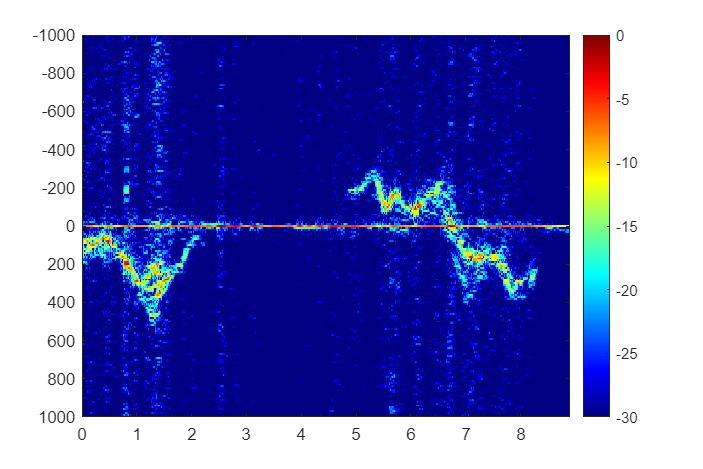


fig2 = figure(2);
set(fig2, 'position', [50, 50, 900, 600]);
plot_A_DT2 = abs(A_TD2');
plot_A_DT2_dB = mag2db(plot_A_DT2 / max(max(plot_A_DT2)));
h2 = imagesc(array_start_time, array_Doppler_frequency, plot_A_DT2_dB);
xlim([array_start_time(1), array_start_time(end)]);
ylim([array_Doppler_frequency(1), array_Doppler_frequency(end)]);
colorbar;
colormap('jet');
clim([thres_A_TRD, 0]);